Prof. Dr. Ralf Hielscher 

Erik Wünsche

TU Bergakademie Freiberg

Summer Semester 2025

# Mathematical Image Processing - Exercise Sheet 2

Download the zip file` sheet2.zip `with the images for the following tasks from OPAL. Please make sure your current working directory (Working directory/Current Folder) in MATLAB matches the folder where the exercises are located.

**Important Tips:**

- Use **Ctrl+Enter** to run a section.

- Use **Ctrl+Alt+Enter** to insert section breaks.

- Use **F9** to execute highlighted code in the command window.

## Part 1: Noise

#### Exercise 1: (Error measures)

We can compare images very well with our eyes. Alternatively, we would like to compare images analytically. For this purpose, various error measurements are examined in the following.

We load the image` capybara.png `and add Gaussian noise with variance $\sigma = 0.01 ,~0.05,~0.1,~0.2,~0.4
$.

Now it is your task to add the error measures 

- MAE (Mean absolute error)               $MAE = \frac1N \|u-v\|_1$

- MSE (Mean square error)                 $MSE = \frac1N \| u-v \|_2^2$

- PSNR (Peak signal to noise ratio)    $PSNR = 10\cdot\log_{10} \left( \frac{(\max(u)-\min(u))^2}{MSE} \right)$

in the matlab script of the function` ErrorMeasure(f,u,method)`. Then look at the results. What is the difference between the known error measures MAE / MSE and the PSNR which is often used in signal and image processing.

% load the capybara.png image and transform the color values to [0,1]
img = rgb2gray(double(imread('capybara.png'))/255);

Error using imread>get_full_filename (line 635)
Unable to find file "capybara.png".

Error in imread (line 395)
        fullname = get_full_filename(filename);
        ^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^^

figure
imshow(img)


% add Gaussian noise of different variances and plot it
fig = figure;
fig.Position(3:4) = [3000,2000];
subplot(2,3,1)
imshow(img)
title('Original')

sigma = [0.01,0.05,0.1,0.2,0.4];
for i=1:length(sigma)
  A{i} = imnoise(img,'Gaussian',0,sigma(i)^2);
  subplot(2,3,i+1)
  imshow(A{i})
  xlabel(['$\sigma$=',num2str(sigma(i),'%.2f')],'Interpreter','latex')
end

Unable to perform assignment because brace indexing is not supported for variables of this type.

Add the MAE, MSE and PSNR Error measure to the` ErrorMeasure.m `Matlab function script and test them on the previous images.

% Compute the Errors
method = ["MAE","MSE","PSNR"];
for i=1:length(sigma)
  for j=1:3
    E(j,i) = ErrorMeasure(A{i},img,method(j));
  end
end

% Display the Errors
array2table(E,"VariableNames",["0.01","0.05","0.10","0.20","0.40"],"RowNames",["MAE","MSE","PSNR"])

ans = 3×5 table
               0.01         0.05         0.10         0.20        0.40  
            __________    _________    _________    ________    ________

    MAE      0.0079585     0.039834     0.078761     0.14714      0.2474
    MSE     9.9507e-05    0.0024929    0.0096444    0.032744    0.092826
    PSNR        40.021       26.033       20.157      14.849      10.323


Compare MAE and MSE. (Maybe use the following chart)

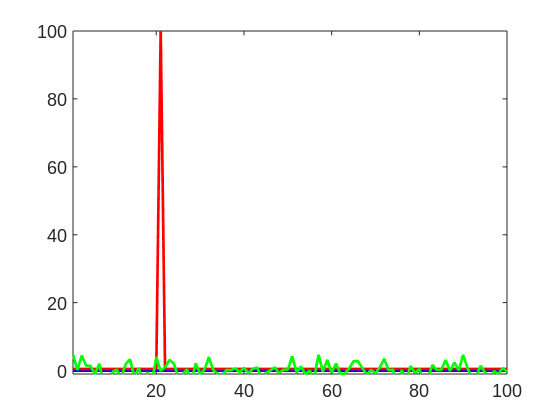

% Construct the following plot
figure
rng(4)
const = zeros(100,1);
plot(1:100,const,'b','LineWidth',2)
ylim([-1,100])
xlim([1,100])
hold on
impulse = [zeros(20,1);100;zeros(79,1)]+0.5;
gaussian = randn(100,1)*2;
plot(1:100,impulse,'r','LineWidth',2)
plot(1:100,gaussian,'g','LineWidth',2)
hold off

% Compute the Errors
method = ["MAE","MSE"];
for i=1:2
    E2(i,1) = ErrorMeasure(const,impulse,method(i));
    E2(i,2) = ErrorMeasure(const,gaussian,method(i));
end

% Display the Errors
array2table(E2,"VariableNames",["Impuls (red)","Gaussian (green)"],"RowNames",["MAE","MSE"])

ans = 2×2 table
           Impuls (red)    Gaussian (green)
           ____________    ________________

    MAE          1.5            1.5035     
    MSE       101.25            4.0009     


#### Exercise 2: (Classes of Noise)

Lets examine some classes of image noise.

- Gaussian noise

- Multiplicative gamma noise

- Impulsive noise

- Salt-and-Pepper noise

- Poisson noise.

To do this, we add noise to the gray-scale image` capybara.png`.

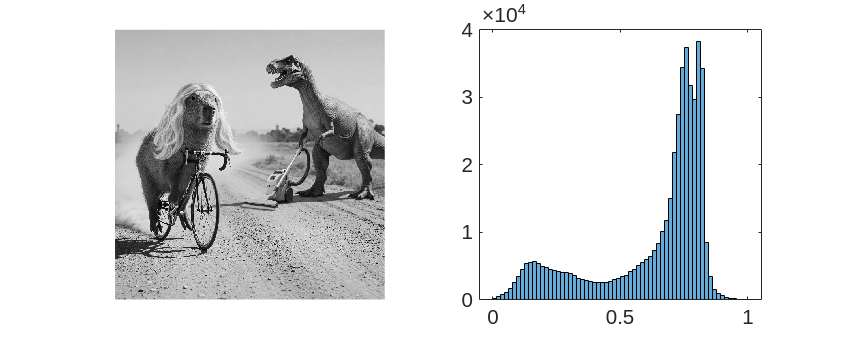

% load and examine the image
img = rgb2gray(imread('capybara.png'));
img = double(img)./255;
fig = figure;
fig.Position(3:4) = [3000,1200];
subplot(1,2,1)
imshow(img)
subplot(1,2,2)
histogram(img,64)

a) White Gaussian noise is additive, i.e. it applies


$$f = u_0 + \eta $$


where $u_0$ is the original image and $\eta$ denotes the noise term, which can be modelled by a vector of random variables $X = (X_i)_{i=1}^{N}$, where the components $X_i$ are independently identically distributed, i.e. $X_i \, \tilde{} \, \mathcal{N}(0,\sigma^2),~i=1,\dots,N$.

Task: Model white Gaussian noise with variable variance $\sigma^2$ and add it to the image. Use the function` randn `and the following statement about the normal distribution:

If $X \tilde{} \mathcal{N}(0,1)$ and $Y \tilde{} \mathcal{N}(\mu,\sigma^2)$ then $Y = \sigma \cdot X + \mu$.

Compare the noisy image with the image, that is obtained by the predefined Matlab command` imnoise.`

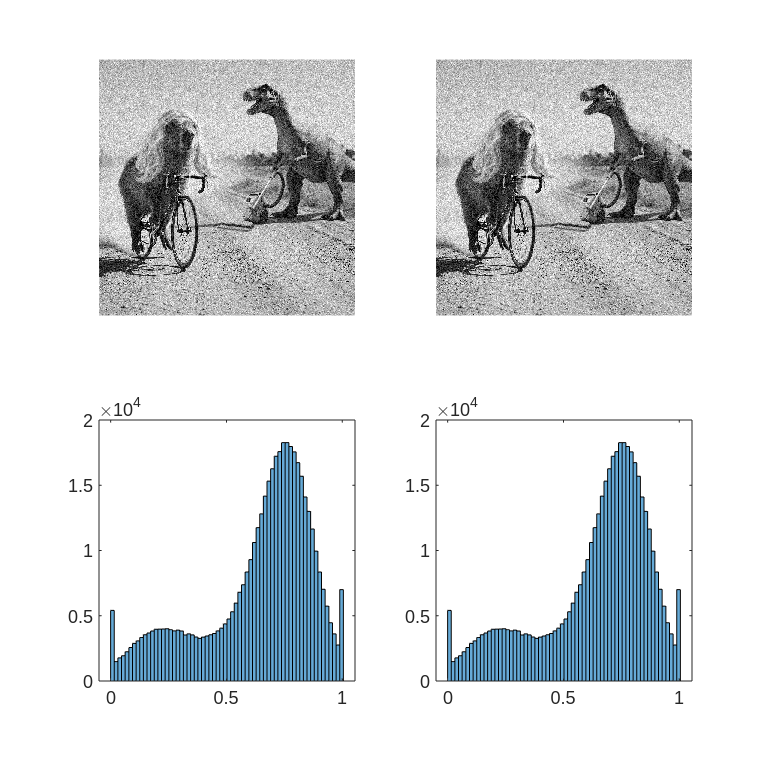

mu = 0;
v = 0.01;

% TODO: Model and add gaussian noise manually
rng('default')
noise = sqrt(v)*randn(size(img)) + mu;
Gaussian1 = img+noise;
Gaussian1(Gaussian1<0) = 0;
Gaussian1(Gaussian1>1) = 1;

% Add gaussian noise by imnoise command
rng('default')
Gaussian2 = imnoise(img,'gaussian',mu,v);

% Plot both next to each other
fig = figure;
fig.Position(3:4) = [3000,3000];
subplot(2,2,1)
imshow(Gaussian1)
subplot(2,2,2)
imshow(Gaussian2)
subplot(2,2,3)
histogram(Gaussian1,64)
subplot(2,2,4)
histogram(Gaussian2,64)

% Difference between both images
E = ErrorMeasure(Gaussian1,Gaussian2,'MSE')

E = 0

b) Gamma noise is a typical example of multiplicative noise. It applies


$$f = u_0 \cdot \eta $$


where $u_0$ denotes the original image and $\eta$ denotes the noise term, which can be modelled by a random vector $X = (X_i)_{i=1}^{N}$. The components $X_i$ are independent identical distributed with respect to the gamma distribution, i.e. $X_i \, \tilde{} \, \Gamma(\alpha,\theta),~i=1,\dots,N$ where $\alpha>0 $ is the shape parameter and $\theta>0$ the scale parameter. The mean satisfies $\mu = \alpha\,\theta$ and the variance $\sigma^2 = \alpha \, \theta^2$. 

*Task:* Use the command` gamrnd `from the* Statistics and Machine Learning Toolbox *to model the gamma noise with $\sigma^2=0.05$ and $\mu=1$.

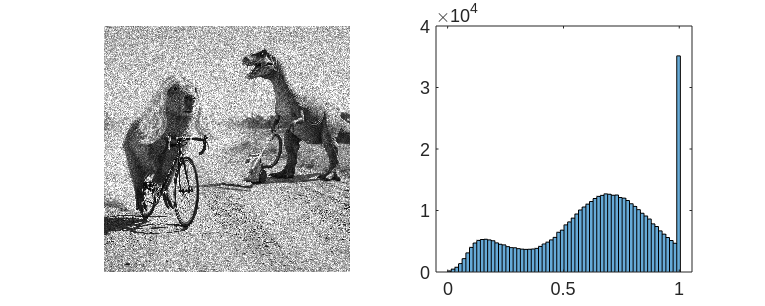

v = 0.05;

% compute the parameter
alpha = 1/v;
theta = v;

rng('default')
% TODO: model and multiply Gamma-noise
gamma_noise = gamrnd(alpha,theta, size(img));
Gamma = img .* gamma_noise;
Gamma = min(max(Gamma,0),1);

fig = figure;
fig.Position(3:4) = [3000,1200];
subplot(1,2,1)
imshow(Gamma)
subplot(1,2,2)
histogram(Gamma,64)

c) Impulsive noise is neither additive nor multiplicative. It is modelled by replacing the colour values in random pixels with uniformly distributed random colour values independent of the initial values.

Task: Add $25 \%$ impulsive noise to the image.

Hint: The command

returns random pixel indices from $d\cdot100\%$ of the pixel. (e.g.: $d=0.25$ returns $25\%$ of the pixel indices of the image). 

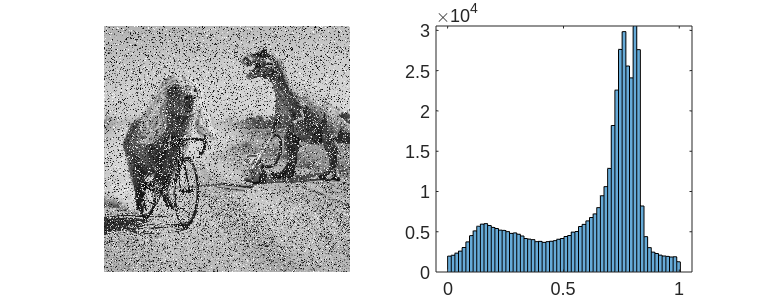

d = 0.25;
% randomly draw 25% of the pixel indices
rng('default')
ind = randperm(numel(img));
noisy_points = ind(1:round(numel(img)*d));

% TODO: add impulsive noise to the image
Impulsiv = img;
Impulsiv(noisy_points) = rand(1,length(noisy_points));

% plot the results
fig = figure;
fig.Position(3:4) = [3000,1200];
subplot(1,2,1)
imshow(Impulsiv)
subplot(1,2,2)
histogram(Impulsiv,64)

d) "Salt-and-pepper noise" is a special case of impulsive noise. Here the colour values are not replaced by random gray values, but only by black and white values.

Task: Model and add $25\%$ "salt-and-pepper noise" to the image manually. 

Create a second noisy image with the` imnoise `command and compare the two noisy images.

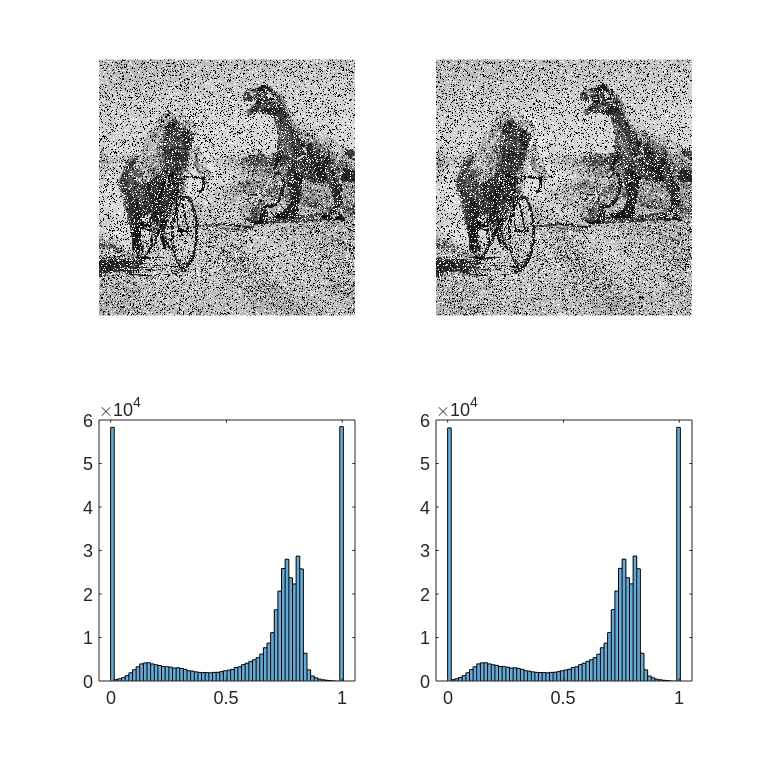

d = 0.25;

% randomly draw 25% of the pixel indices
rng('default')
ind = randperm(numel(img));
noisy_points = ind(1:round(numel(img)*d));

% TODO: add salt and pepper noise to the image
SaltandPepper1 = img;
SaltandPepper1(noisy_points) = round(rand(1,length(noisy_points)));

% add salt and pepper by imnoise command
rng('default')
SaltandPepper2 = imnoise(img,'salt & pepper',d);

% Plot both images
fig = figure;
fig.Position(3:4) = [3000,3000];
subplot(2,2,1)
imshow(SaltandPepper1)
subplot(2,2,2)
imshow(SaltandPepper2)
subplot(2,2,3)
histogram(SaltandPepper1,64)
subplot(2,2,4)
histogram(SaltandPepper2,64)

d) Poisson noise is neither additive nor multiplicative. Let $u_0$ be an original un-noised image, then we can model the components of the Poisson-noisy image $u = (u_i)_{i=1}^N$ by $u_i \, \tilde{} \, Pois(u^0_i)$ for $i=1,\dots,N$.

*Task:* Use the command` poissrnd `from the *Statistics and Machine Learning Toolbox* and generate the poisson noise manually.

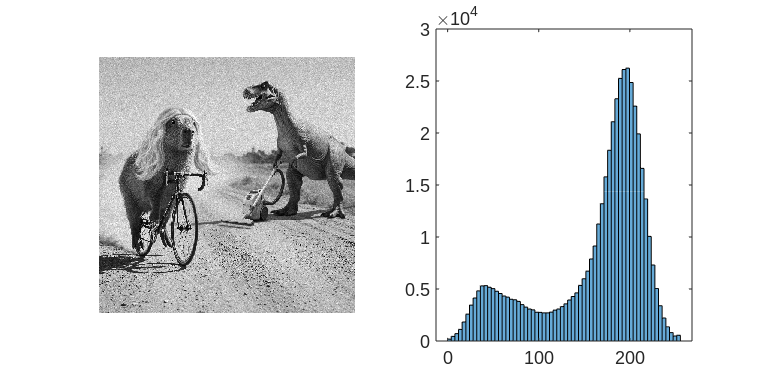

% TODO: model poisson noise
rng('default')
Poisson = uint8(poissrnd(round(img*255)));

% Plot both images
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(Poisson)
subplot(1,2,2)
histogram(Poisson,64)

e) Compare the histograms of the input image with the noisy images.

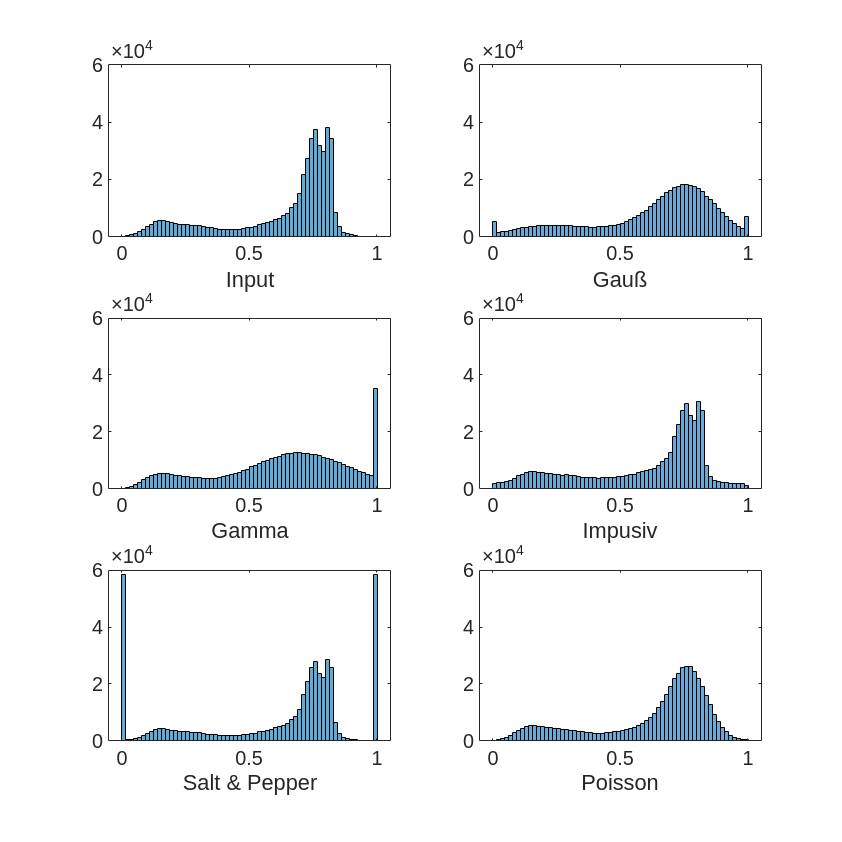

% plot all of the histograms
fig = figure;
fig.Position(3:4) = [3000,3000];
subplot(3,2,1)
histogram(img,64)
ylim([0,6*10^4])
xlabel('Input')
subplot(3,2,2)
histogram(Gaussian1,64)
ylim([0,6*10^4])
xlabel('Gauß')
subplot(3,2,3)
histogram(Gamma,64)
ylim([0,6*10^4])
xlabel('Gamma')
subplot(3,2,4)
histogram(Impulsiv,64)
ylim([0,6*10^4])
xlabel('Impusiv')
subplot(3,2,5)
histogram(SaltandPepper1,64)
ylim([0,6*10^4])
xlabel('Salt & Pepper')
subplot(3,2,6)
histogram(double(Poisson)/255,64)
ylim([0,6*10^4])
xlabel('Poisson')

## Part 2: Smoothing of Images

You will need the Image Processing Toolbox of Matlab (Installation: Home -> Add-Ons -> Image Processing Toolbox).

In the following we take a look on different linear filters and nonlinear filters. Therefore we will test this filters on the images` capybara_Gaussian.png `(white Gaussian noise) and` capybara_SaP.png `(salt-and-pepper noise).

% capy = rgb2gray(double(imread('capybara.png'))/255);
% figure
% imshow(capy)
% capy1 = imnoise(capy,'gaussian');
% imwrite(capy1,'capybara_Gaussian.png')
% capy2 = imnoise(capy,'salt & pepper',0.2);
% imwrite(capy2,'capybara_SaP.png')

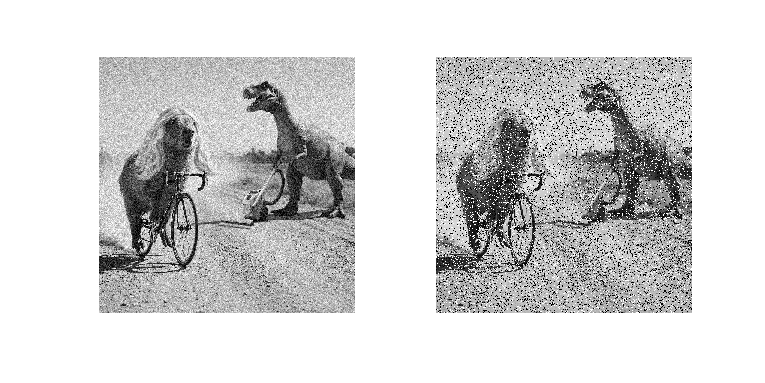

% load and plot the input images
imgG = double(imread('capybara_Gaussian.png'))/255;
imgSaP = double(imread('capybara_SaP.png'))/255;
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(imgG)
subplot(1,2,2)
imshow(imgSaP)

#### Exercise 3: (Linear Smoothing Filters)

a) **Mean Filter**

The Mean-Filter is the simplest example of a linear filter.

Implement a function` U = mean_filter(F,s) `that uses the mean-Filter on the image` F`. Therefore each pixel value is replaced by the mean value of the "neighbouring" pixels. This neighbourhood is described by a square of size $(2s+1)\times(2s+1)$ centered on the pixel which is replaced.

Do not use more than two loops. Can you manage to use fewer loops?

Test your method on the images` imgG `and` imgSaP `with parameters $s\in\{1,2,5\}$. 

Which parameter achieves the best result for which image? You are also welcome to try out other parameters.

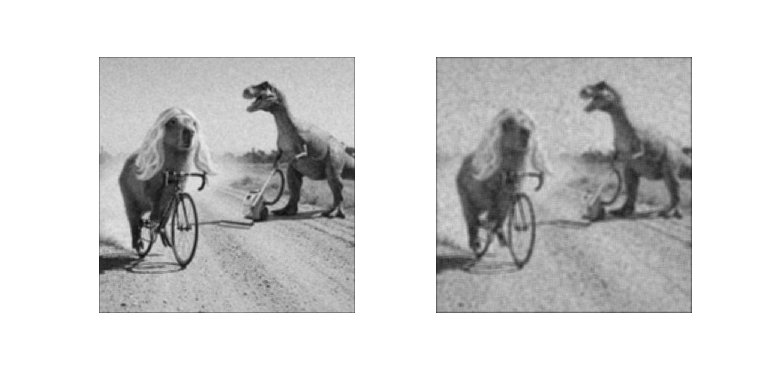

% apply the mean filters to the image
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(mean_filter(imgG,3))
subplot(1,2,2)
imshow(mean_filter(imgSaP,5))

b) **Sampled Gaussian Filter** 

Implement a function` U = gaussian_filter(F,s) `for a Gaussian filter $K_{\sigma}$. Use a mask of size $(2s+1)\times(2s+1)$.

The filter is descried by a mask 

                  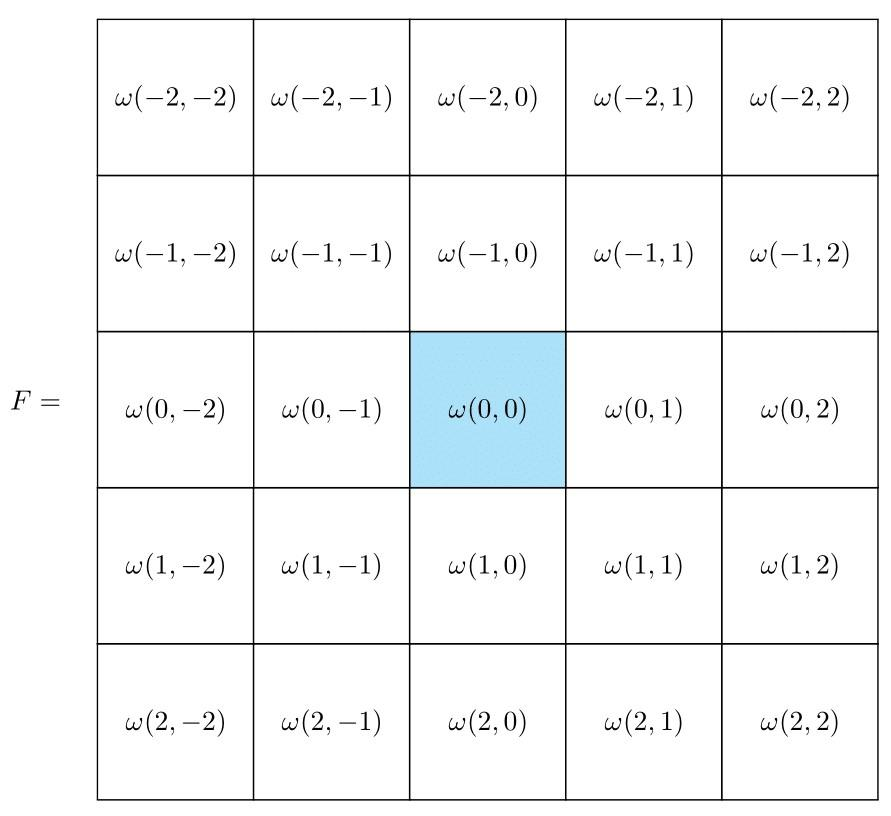

The values follow a Gaussian function and fulfil the equation

$\sum\limits_{(i,j)} \omega(i,j) = 1, \quad \omega(i,j)\geq0$.

The Gaussian function

% sigma = 1;
% s=2;
% [X,Y] = meshgrid(-3:0.2:3,-3:0.2:3);
% R = sqrt(X.^2 + Y.^2);
% K = 1/sqrt(2*pi*sigma^2) * exp(-(R).^2/(2*sigma^2));
% 
% surf(X,Y,K)

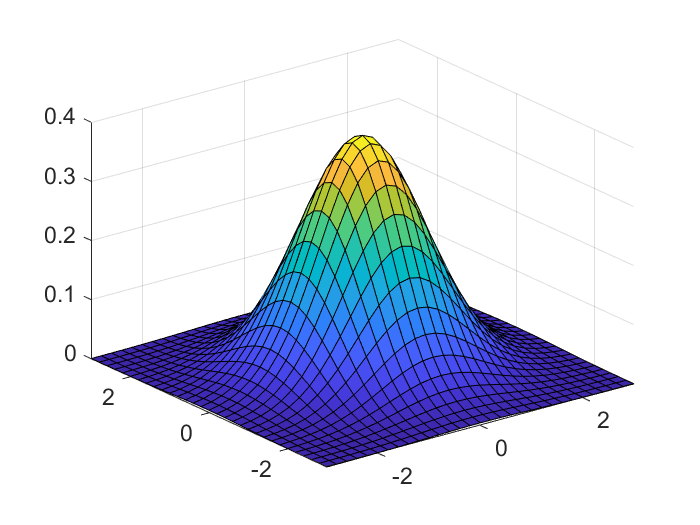

with mean value $0$ and standard deviation $\sigma$ is defined by

$K_{\sigma} (x) = \frac1{\sqrt{2\pi\sigma^2}}\,\mathrm e^{-\|x\|_2^2/2\sigma^2}$.

The function is truncated outside of the circle with radius $3\sigma$ ($B_{3\sigma}(x) = \{ x ~ | ~ \|x\|_2 \leq 3\sigma \}$), i.e. it is set to $0$.

Tip: Compute $\sigma$ from $s$. 

Finally, the resulting filter is normalised.

Test your function on the images` imgG `and` imgSaP.`

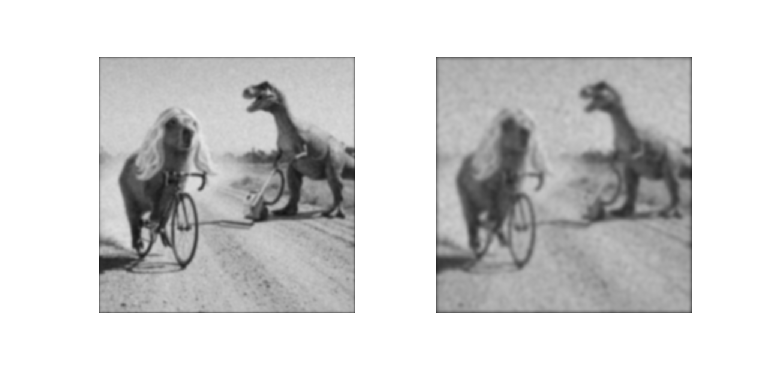

% apply the gaussian filter
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(gaussian_filter(imgG,10));
subplot(1,2,2)
imshow(gaussian_filter(imgSaP,16));

#### Exercise 4: (Window Size)

Investigate the dependence of the intensity of the noise on the window size.

Therefore we load the image` capybara.png`, add gaussian white noise with standard deviation $\sigma \in\{0.009, \, 0.01, \, 0.2, \, 0.5, \, 2 \}$ and denoise it afterwards with the `gaussian_filter()`. Then we compare the error of the denoised image to the original image with respect to different window sizes.

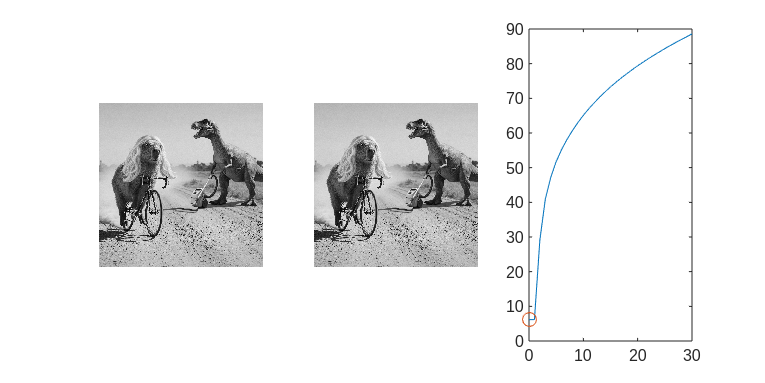

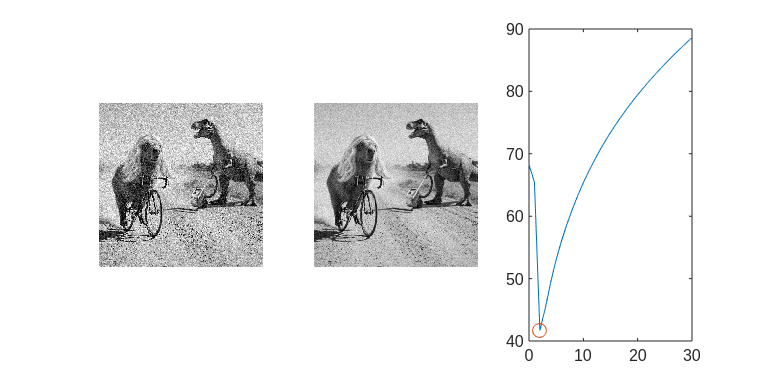

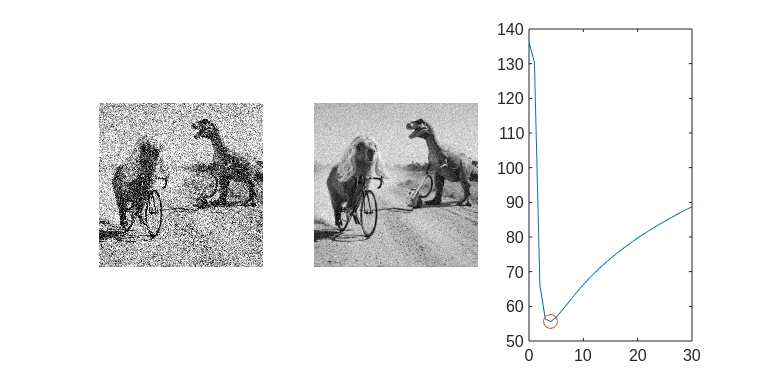

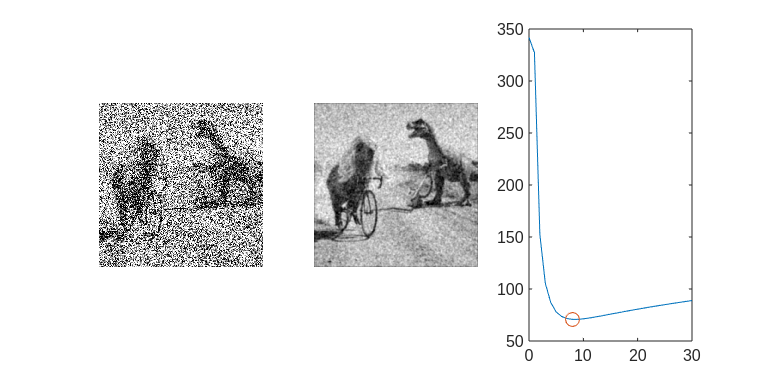

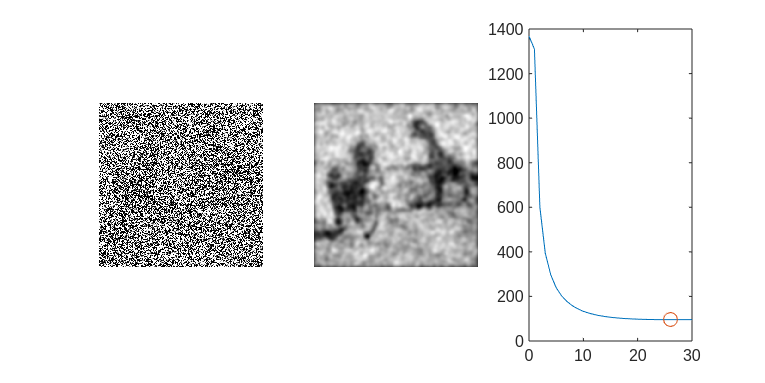

% load image
u0 = rgb2gray(double(imread('capybara.png'))/255);

for sigma = [0.009,0.1,0.2,0.5,2]
 
  % add noise
  eps = sigma*randn(size(u0));
  u = u0 + eps;

  % TODO: Smooth and Compute the Error for different window sizes 0:...
  clear Error;
  for n = 0:30
    u_sm = gaussian_filter(u,n); 
    Error(n+1) = norm( u0(:)-u_sm(:) );
  end
  
  % Plot the results and mark the min
  fig = figure;
  fig.Position(3:4) = [3000,1500];
  subplot(1,3,1)
  imshow(u)
  subplot(1,3,3)
  plot(0:length(Error)-1,Error)
  hold on
  [a,b] = min(Error);
  plot(b-1,a,'o')
  hold off
  subplot(1,3,2)
  imshow(gaussian_filter(u,b-1))
end

#### Exercise 5: (Median Filter (non-linear))

The Median-Filter is the simplest example of a non-linear filter.

Implement the function` median_filter(F,s) `which calculates the median of the neighbourhood values. Use as few loops as possible!

Test your method on the images` imgG `and` imgSaP `with parameters $s\in\{1,2,5\}$. Which parameter achieves the best result for which image? You are also welcome to try out other parameters.

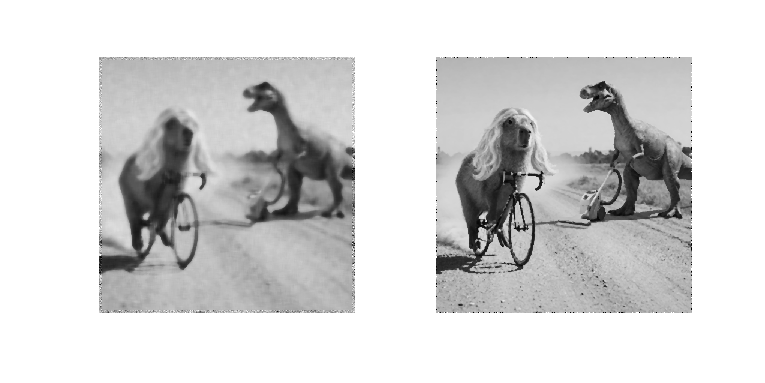

% apply the medaian filter
fig = figure;
fig.Position(3:4) = [3000,1500];
subplot(1,2,1)
imshow(median_filter(imgG,7))
subplot(1,2,2)
imshow(median_filter(imgSaP,2))

#### Exercise 6: (Denoising)

a) Compare and classify the filters from exercise 1 and 2 with regard to their effect on the different types of noise.

Try to explain why a certain filter works well with certain kind of noises.

b) Load the image` noisyData.png `and take a look on the histogram. 

% figure
% img = rgb2gray(double(imread('affe.jpg'))/255);
% img = imnoise(img,'salt & pepper',0.75);
% subplot(1,2,1)
% imshow(img)
% subplot(1,2,2)
% imshow(mean_filter(img,6))

Depending on the noise, choose your favorite filter and smooth the image. What do you see?

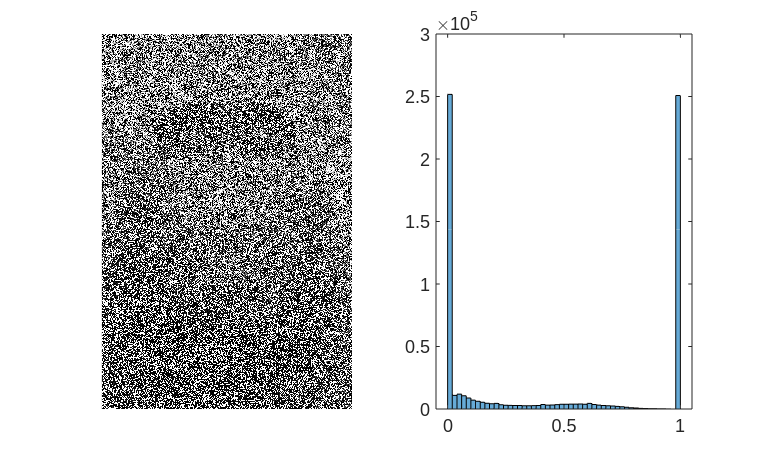

img = double(imread('noisyData.png'))/255;

fig = figure;
fig.Position(3:4) = [3000,1800];
subplot(1,2,1)
imshow(img)
subplot(1,2,2)
histogram(img)

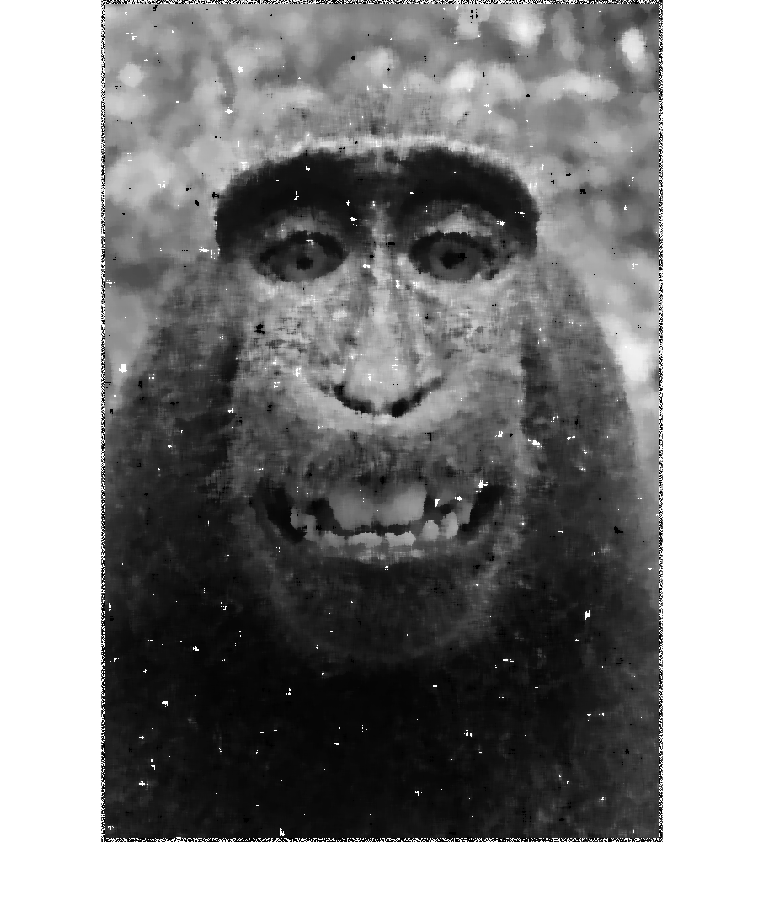

fig = figure;
fig.Position(3:4) = [3000,1800];
% TODO: Denoise
imgD = median_filter(img,5);
imshow(imgD)